# Datastore

今天要讀的資料集，是 NIH Clinical Center 在 2017 年公開的 x-ray images

這個資料集有 112120 張 X 光照片影像 (來自 30805位病人)，主要是用來診斷肺部疾病時用的

那今天會取出 14 種疾病 各 10 張影像來做 demo

(取自陽明大學盧家峰課堂資源)

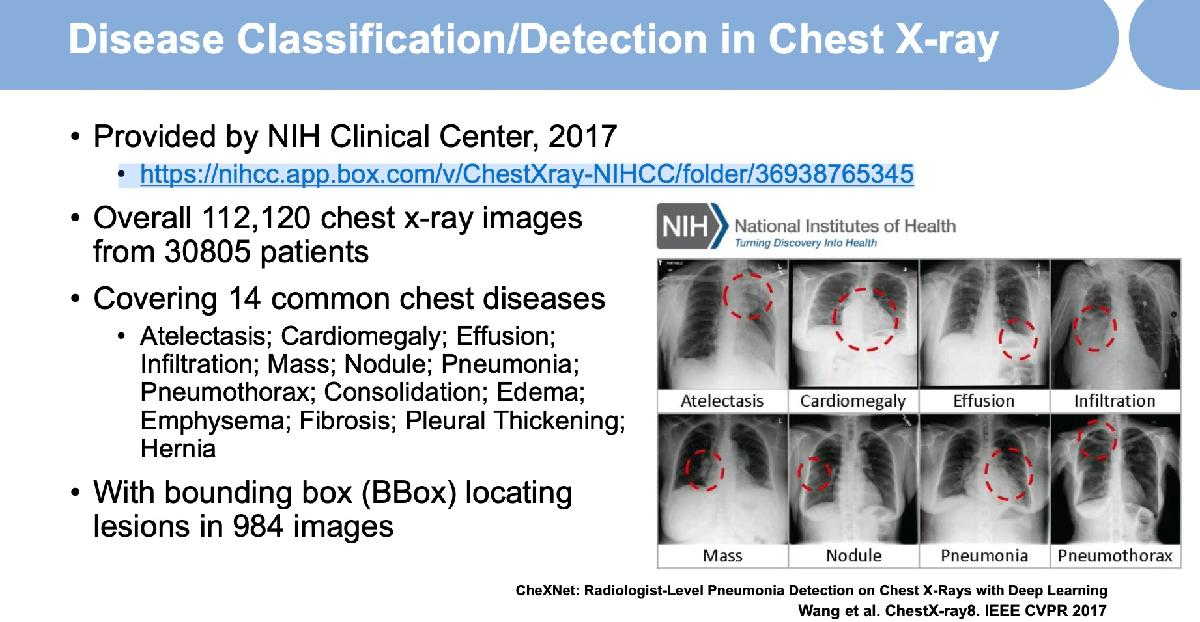

## 常用影像 function

- imread:

- imfinfo

- imshow

- imwrite

- rgb2gray

- imagesc: sc是scale，是自動幫你把對比度調到 full range

imdata = imread('MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png');
imshow(imdata)


info = imfinfo('MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png')

info = struct with fields:
                  Filename: '/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png'
               FileModDate: '14-Jul-2017 00:56:56'
                  FileSize: 371456
                    Format: 'png'
             FormatVersion: []
                     Width: 1024
                    Height: 1024
                  BitDepth: 8
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
               

## Datastore

datastore 同時是一個 function，也是種 datatype

當我們用 `datastore(location, 'type', TYPE)` 時，他就是個 function，此時，他會

- 去你指定的 location(e.g. excel 所處的 folder，或 image 所處的 folder) 讀檔

- 讀什麼檔，就用 'type' 這個 argument �後面的 TYPE 來做決定。這個 TYPE 你可以寫成：

- 'image': 讀 image files

- 'spreadsheet': 讀 excel 檔

- 'tabulartext': 讀 tabular text files

- 'database': 可以接資料庫

- ....

function 執行完後，return 給你的，就會是 `datastore` 這種 data type 的物件。

其實，如果你很確定你就是要讀影像，那可以用 `imageDatastore`，那就不需要寫 `'type', 'image'` 這段。而類似的作法如下：

- ImageDatastore

- TabularTextDatastore

- SpreadsheetDatastore

- FileDatastore

- KeyValueDatastore

- DatabaseDatastore

### image

直接上例子：

dirname = './MLmaterials_L3/dataset'

dirname = './MLmaterials_L3/dataset'

ds = datastore(dirname, ... % 讀檔的路徑 (folder 路徑)
    'type', 'image',... % 讀檔類型，是 image
    'IncludeSubfolders', true,... % 如果 dirname 底下，還有資料夾，是否一路 nested 的讀下去？
    'LabelSource','foldernames',... % 監督學習的 label，直接用影像所處的資料夾來命名
    'ReadFcn', @customreader) % 看到 @ 後面接一個單字，那個單字就是 function name -> 所以要使用我自定義的 function

ds =   ImageDatastore with properties:

                       Files: {
                              ' .../data_types/MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png';
                              ' .../data_types/MLmaterials_L3/dataset/Cardiomegaly/00000661_000.png';
                              ' .../data_types/MLmaterials_L3/dataset/Cardiomegaly/00003394_006.png'
                               ... and 27 more
                              }
                     Folders: {
                              ' .../matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset'
                              }
                      Labels: [Cardiomegaly; Cardiomegaly; Cardiomegaly ... and 27 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
      

可以看到，讀檔時，我用了自己的 `customreader`，那這樣做，是因為我有既定的前處理過程，這樣做就比較方便

看一下 customreader 的內容：

可以看到，他就是讀檔後，如果發現你是灰階影像，他會幫你把灰階影像複製三次，變成 3-d array，最後，再把 image 做 resize 成 512x512

可以發現，這種作法，就是為了和 deep learning 的 method 作介接，因為常用的 pretrained 網路，都只吃 3-d array，以及需要的 dim (e.g. 這邊的 512x512)

讀完後，這個 ds 就是一個 object 了，他此時並沒有真的把所有影像讀入，他只是讀位子資訊而已。所以可以查一下相關的資訊：

ds.Files % 所有要讀的檔名的絕對路徑

ans = 30×1 cell array
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00000661_000.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00003394_006.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00005066_030.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00009608_024.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00011463_002.png'}
    {'/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/m

ds.Labels % 每個影像他的 labels

ans = 30×1 categorical array
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Cardiomegaly 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Mass 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 
     Pneumonia 


ds.countEachLabel % 看各個 label 的 count

ans = 3×2 table
       Label        Count
    ____________    _____

    Cardiomegaly     10  
    Mass             10  
    Pneumonia        10  


ds.ReadSize % 接下來讀檔時，一次讀幾張？

ans = 1

% ds.ReadSize = 5 % 設定成，一次讀 5 張

接下來，就是用 `ds.read` ，一次讀 1 張影像進來，舉例來說：

[img, info] = ds.read; % 讀第一張影像進來，會 return一張 img，以及 info
imshow(img)

info

info = struct with fields:
    Filename: '/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_intro/matlab_official_docs/data_types/MLmaterials_L3/dataset/Cardiomegaly/00000211_041.png'
    FileSize: 371456
       Label: Cardiomegaly


如果要一次讀全部影像，就這樣做：

imgall = ds.readall;

此時的 imgall，是一個 cell array，裡面每一個 cell，都是一張影像的 2d or 3d array

會用 cell array 來存，是因為他不確定你每張影像的 shape (e.g. 有些灰階，有些RGB，且大小也可能都不同)，所以用 cell array 來存。

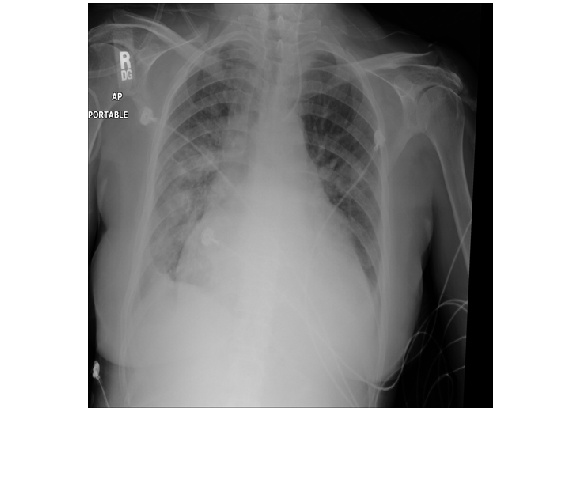

imshow(imgall{1})

接下來，如果在 deep learning 世界，會需要把資料的順序打亂，那有這個 function 可以用

shuffle_ds = ds.shuffle % 把裡面的資料打亂順序後，再存為新的 datastore 物件，叫 shuffle_ds

最後，講一下 partition。可以把資料分割成不同的 part，然後開多核心來處理，範例 code 如下：

這樣，就可以做平行處理了。

最後，把剛剛介紹過的 function，整理如下：

- datastore: create a datastore

- read: 用 `ds.read`，他就會讀一張影像，再做 ds.`read` ，就讀第二張，以此類推。如果一次不想只讀一張，就用 ds.ReadSize = k 來設定成一次讀 k 張。

- readall: 一次讀完全部

- hasdata: check 這個物件裡面，有沒有 data

- partion: 把資料集，分成 training, testing 之類的

- numpartitions: estimate a reasonable number of partitions

### tabular text

跟剛剛的概念很像，只是差在：

- img 是 folder - img 的關係，這邊會變成 csv - row 的關係。所以讀 img 時，是給他 folder 路徑，但讀 tabular text 時，是給他 csv file 的路徑

- img 時，建立完 datastore 物件後，是用 ds.read 一次讀 k 張影像(k預設為 1)，tabular text 時，是用 ds.read 一次讀 k 個 rows (預設為 20000)

現在來讀一張，有 11 萬個 rows 的 csv，那建立 datastore 物件如下：

ds = datastore('MLmaterials_L3/Data_Entry_2017.csv', 'type', 'tabulartext');

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../matlab_official_docs/data_types/MLmaterials_L3/Data_Entry_2017.csv'
                             }
                    Folders: {
                             ' .../matlab_intro/matlab_official_docs/data_types/MLmaterials_L3'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'ImageIndex', 'FindingLabels', 'Follow_up_' ... and 8 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%q', '%q'

ds

可以看一下欄位名稱

ds.VariableNames

ans = 1×11 cell array
    {'ImageIndex'}    {'FindingLabels'}    {'Follow_up_'}    {'PatientID'}    {'PatientAge'}    {'PatientGender'}    {'ViewPosition'}    {'OriginalImage_Width'}    {'Height_'}    {'OriginalImagePixelSpacing_x'}    {'y_'}


預設一次讀 20000 個 rows

ds.ReadSize

ans = 20000

讀一次看看：

tabledata = ds.read

tabledata = 20000×11 table
         ImageIndex               FindingLabels           Follow_up_    PatientID    PatientAge    PatientGender    ViewPosition    OriginalImage_Width    Height_    OriginalImagePixelSpacing_x     y_  
    ____________________    __________________________    __________    _________    __________    _____________    ____________    ___________________    _______    ___________________________    _____

    {'00000001_000.png'}    {'Cardiomegaly'          }        0             1            58            {'M'}           {'PA'}              2682             2749                 0.143          

可以看到，他回給你 table array，可以點 workspace 裡面的 tabledata 變數，就可以看到一張 table

## table array

% 取某一欄
tabledata.PatientAge

ans =     58
    58
    58
    81
    81
    74
    75
    76
    77
    78



% 取某兩欄 -> output 為 table
tabledata(:, 3:4)

ans = 20000×2 table
    Follow_up_    PatientID
    __________    _________

        0             1    
        1             1    
        2             1    
        0             2    
        0             3    
        1             3    
        2             3    
        3             3    
        4             3    
        5             3    
        6             3    
        7             3    
        0             4    
        0             5    
        1             5    
        2             5    



% 取某兩欄 -> output 為 array (只取 table 裡面的值)
tabledata(:, 3:4).Variables

ans =      0     1
     1     1
     2     1
     0     2
     0     3
     1     3
     2     3
     3     3
     4     3
     5     3



% 看欄位名稱
tabledata.Properties.VariableNames

ans = 1×11 cell array
    {'ImageIndex'}    {'FindingLabels'}    {'Follow_up_'}    {'PatientID'}    {'PatientAge'}    {'PatientGender'}    {'ViewPosition'}    {'OriginalImage_Width'}    {'Height_'}    {'OriginalImagePixelSpacing_x'}    {'y_'}


還有一堆功能，就自己去探索：

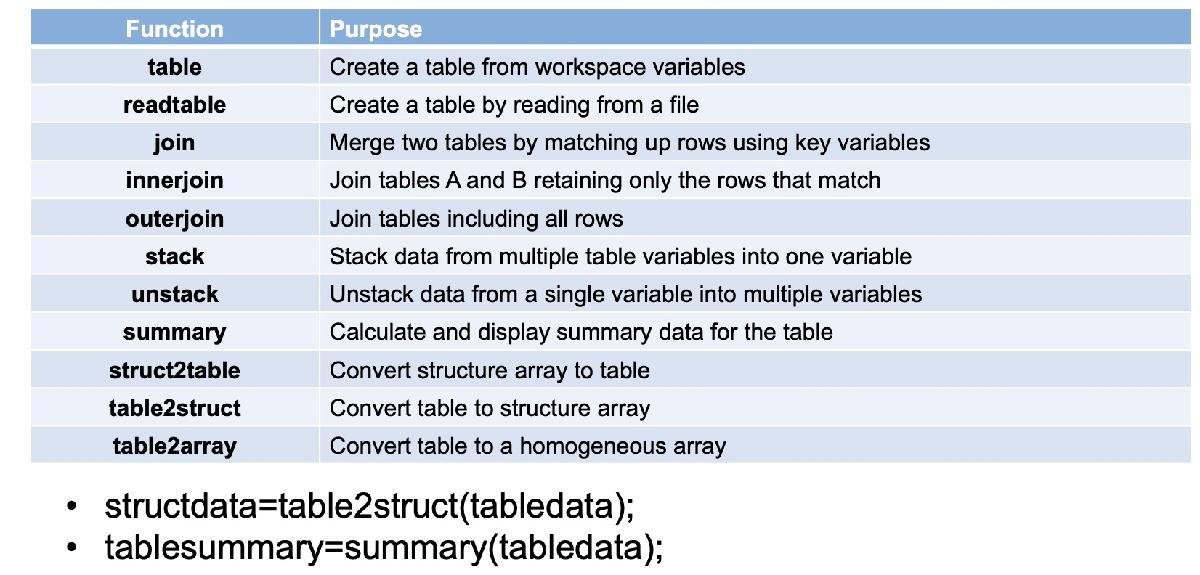

來簡單玩幾個：

summary(tabledata)

Variables:

    ImageIndex: 20000×1 cell array of character vectors

    FindingLabels: 20000×1 cell array of character vectors

    Follow_up_: 20000×1 double

        Values:

            Min           0   
            Median        3   
            Max         136   

    PatientID: 20000×1 double

        Values:

            Min            1  
            Median      2587  
            Max         5348  

    PatientAge: 20000×1 double

        Values:

            Min           2   
            Median       49   
            Max          94   

    PatientGender: 20000×1 cell array of character vectors

    ViewPosition: 20000×1 cell array of character vectors

    OriginalImage_Width: 20000×1 double

        Values:

            Min         1517  
            Median      2500  
            Max         3056  

    Height_: 20000×

### hands on example

現在來做個範例，就是我資料夾裡面，有一堆 txt 檔，那要怎麼做？